# Image Processing 

A light introduction to image processing in MATLAB

## Important Settings

#### Add functions

Add the Salcedo Files folder from the MATLAB drive to the search path. We will use these functions for some of our processing

### Custom Documentation

To access the custom documentation, you need

- Install the MATLAB Drive Connector

- Wait for everything to sync on your computer (Green Check in the Connector)

- Add the SALCEDO Files folder to your Search Path

If everything goes as planned, then you should see the following in the Category list when you bring up the documentation

Click on the "Mastering MATLAB Toolbox" to get started

## Memory

Image files (and especially image stacks) can take up a lot of memory. To speed things up, you should crank up your Java Heap Memory. You can change this in the Preferences Panel (in Home Tab). I recommend cranking the slider right to the maximum value

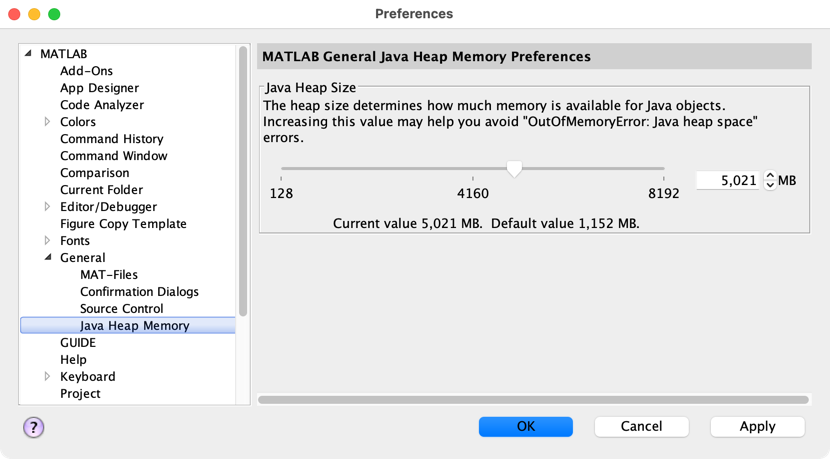

## Reset MATLAB

clearvars % clear the variables
clc % clear the command
close all % close all open windows

Its usually best practice to clear any variables or previous function calls you may have run before you get started

## Find Data Folder

When you first launch MATLAB, it automatically opens a folder on your computer. This code changes that "current folder" to a folder of your choosing. Choose the folder that contains the files from the class exercise. The function **cd** changes the current folder  (current directory) to the one you select using your os file browser. 

data_path = uigetdir;
cd(data_path)

# Grayscale Image processing

## Example 1: Blobs

### Read the image and display

We use the function **imread** to read in the image. This code assumes that you are currently in the same folder as the image. 

img = imread("blobs.tif");

- Review the **img** variable in the workspace

- notice that the image is read in as a numerical 2D matrix with rows and columns

- Notice the class of the variable. What bit-depth is the image?

The function **imtool **is the built-in image viewer app with all the bells and whistles

imtool(img)

If we simply want to add an image to a figure (without any of the **imtool** functionality), we use the function **imshow**

figure;
imshow(img)

### Display the image histogram

the function **imhist** displays the image histogram

imhist(img)
disp(max(img(:)))

- Nice distribution of pixel intensities

- Can you tell the bit-depth from the histogram?

### Read the metadata of the image

All images have metadata imbedded into the file. You read metadata using **imfinfo **as follows:

metadata = imfinfo("IXMtest_A09_s1_w1CE70AD49-290D-4312-82E6-CDC717F32637.tif")

Reviewing the *metadata* structure, you can see:   

- the image is 8-bit image

- Saved as a tif

- its dimensions are  256X256 (Width X Height)

### Enhance Contrast

Often, you may want to start image processing by enchancing the contrast

The function **imadjust** enhances contrast by using an algorithm to stretch the image histogram

figure
img_adj = imadjust(img);

We can then compare the two images side by side using the **nexttile **function

tiledlayout("flow","TileSpacing","none")
nexttile
imshow(img); title('original')

nexttile
imshow(img_adj); title('adjusted')

- the adjusted appears to have a darker background

### Review the histograms

Here we use the old standby **subplot** to tile the plots (because **imhist** doesn't work with **nexttile)**

figure
subplot(1,2,1)
imhist(img)
title('original')

subplot(1,2,2)
imhist(img_adj)
title('adjusted')

- notice how the histogram is now stretched to cover the entire dynamic range of the image

- Also notice that a small percentage of the pixels are now saturated or clamped (have a value of either 0 or 255). Look for the blue lines on either edge of the histogram

- Saturation is one of the main problems of using integer classes for image process and is something to always keep in mind

## Image Segmentation

Often in image processing, you are interested only in a subset of the pixels (e.g. those bright blobs of pixels). One basic way to segment is to threshold or binarize a image by analyzing the histogram and coming up with a cut-off point.

For example, if we look at the histogram, we can see that we have bimodal distribution of black vs white pixels

xline(125,'r--')

For something this straightforward, we can easily use a logical operation to capture the white blobs in a logical array, as follows

mask = img_adj > 125; % create the mask
figure
imshowpair(img_adj, mask, 'montage')

- As you can see, the variable ***mask*** is a logical array with ones in the corresponding locations of the white blobs in the original image

- so, was 125 the best cut-off value?

- Is there a better way to do this other than just eyeballing it?

### Image Segmenter App

Fortunately, there is. And the easiest way to explore this is through the ImageSegmenter app, which you can open from the Apps Tab or by simply using a function call, as follows:

imageSegmenter(img_adj)

Steps:

- Adjust Image

- Threshold

- Use Global Threshold

- Create Mask

- Export

Add code from export here and display the results

- Pretty good, but it looks like we captured some background noise as positive signal

## Morphological Operations

Often after creating a mask, there is often noise that needs to be cleaned up, or connected components that need to be separated. This is accomplished through the use of Morphological Operations. As you can tell from the name, these operations are based on the shapes of the connected components. There are a lot of operations that you can perform, but here we are going to focus on a few simple ones:

- Dilate

- Erode

- Open

- Close

To start, lets return to the image segmenter. Make sure the app still has the mask that you created in the previous step. If not, quickly repeat those steps. 

Then

- Click  on the Morphology Icon

- Select the different morphological operations and play around with the settings

- Which operation can be used to eliminate the small patches of noise?

- Be sure to click on the Apply button when you are done. 

After Morphology, try the clear borders button.

- This eliminates any connected components that are touching the edges of the image (and are likely incomplete)

Finally, export the function. Paste the code here:

- what's been added to our processing steps?

## Filtering Images

Sometimes there is so much noise in an image that morphological operations don't do a good job of cleaning the masks or overly distort the masks in a way that reduces their usefulness. 

This is why it is often beneficial to filter an image before you threshold it, to help smooth out any noise, and hopefully avoid having to use aggressive morphological operations on the mask. A gaussian or median filter can often do the trick. Gaussian filters blur images and median filters help clean up salt and pepper noise

Filters are based on kerning. Kernels are small matrices, e.g. 3x3 grid of numbers, that are applied to every pixel in an image to do things like replace a pixel intensity with the median intensity in the surrounding 9 pixels, and so on.  Often it is hard ton know, what size kernel to use. Luckily, you can use the power of MATLAB to quickly test out a bunch of options.

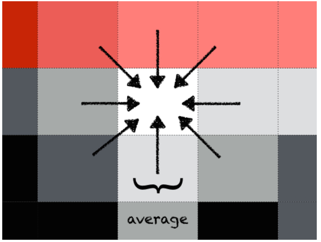

For example, the function **imgaussfilt** applies a gaussian filter to an image and it requires a second input of Sigma, to help determine the standard deviation of the smoothing kernel. We can quickly test a series of sigma values using a FOR LOOP, as follows:

figure
tiledlayout("flow","TileSpacing","compact")
nexttile
imshow(img_adj)
title('original')

sigma = [0.5 1 2 3 5]; % preset the sigma values you want to test

for n=1:numel(sigma)
nexttile
imgf = imgaussfilt(img_adj,sigma(n));
imshow(imgf)
title(sprintf('∑=%1.1f',sigma(n)))
end

- what happens if you change the sigma values (try adding a few larger numbers to the array)?

- This is what makes **nexttile** so useful: you don't need to decide beforehand how many tiles you want in a figure

### Median Filters

The function **medfilt2** applies a median filter to an image. The second input is optional, but you can use it to change the kernel size. For example, the default is 3X3, which can be inputted as vector: [3 3]

So, how would you modify the previous code to test the following kernels

- 1x1

- 2x2

- 3x3

- 5x5

- 9x9

### Segment a filtered image

Once you have the filter you want, you can simply input the filtered image into **imbinarize **function. 

Here, we compare masks created from an unfiltered and filtered image. 

figure
tiledlayout(1,3,"TileSpacing","none")

nexttile
imshow(imbinarize(img_adj)); title('original') % 

nexttile
img_gauss = imgaussfilt(img_adj,2);
bw_gauss = imbinarize(img_gauss);
imshow(bw_gauss); title('gaussian')

nexttile
img_med = medfilt2(img_adj, [5 5]);
bw_med = imbinarize(img_med);
imshow(bw_med); title('median filter')

- notice that we  have fewer noise speckles in the gaussian filtered images, but the median filter still has some

The function **bwareaopen **is really useful for get rid of small noise. You simply input a blob size cut-off and the function removes anything with an area smaller than the cut-off 

bw_gauss = bwareaopen(bw_gauss,10); % remove blobs with areas smaller than 10
figure;
imshow(bw_gauss)

- that looks pretty good. 

We probably don't want to analyze the half-blobs. The function **imclearborder** removes any connected components touching the edges

bw_gauss = imclearborder(bw_gauss); % remove blobs from edges

It's always a good idea to compare the mask to the original image. The function **imshowpair **makes it really easy to overlay the two, as follows:

imshowpair(img,bw_gauss)

- This looks good

- Let analyze those blobs

## Region Properties

The region properties app is a great way to explore all of the properties MATLAB can calculate

imageRegionAnalyzer(bw_gauss)

### regionprops function

Here we analyze the properties of the blobs using the **regionprops **function. By including the original image as the third input, we can also get information on the pixel intensities inside the each region

**regionprops** returns a table, *rp, *when the first input is "table". Otherwise it returns a structure. 

rp = regionprops("table",bw_gauss,img,"all")

### Are areas normally distributed?

Now that we have the data, we can perform some simple analysis

figure
histogram(rp.Area,10)
xlabel('Area (px^2)')
ylabel('frequency')

- doesn't appear so

### Is there a correlation between size and intensity?

The field "MeanIntensity" contains the mean intensity inside each blob

We can use the function **scatter** to plot Area vs Mean Intensity 

figure
scatter(rp.Area,rp.MeanIntensity)
xlabel('Area (px^2)')
ylabel('mean intensity')
ylim([0 255])

- there does not appear to be a strong correlation between size and area

The function **corr** returns the correlation between the two variables

c = corr(rp.Area,rp.MeanIntensity) 

### What's circularity?

The function **regionprops** returns many properties, one of which is termed "circularity". As we can see in the following figure, circularity is a value that indicates how round a given blob is (The value is calculated as a ratio between the perimeter and the area of each blob). Values below 1 are not as circular.

figure;
imshow(img)
for n=1:height(rp)
    text(rp.Centroid(n,1), rp.Centroid(n,2),sprintf('%1.2f',rp.Circularity(n)),"Color",'m')
end
title("Circularity")

## Example 2: Real World data

clearvars -except data_path
clc

file_path = fullfile(data_path,"Week1_150607_C02_s3_w1E54F0108-F44A-4F6E-9637-6A9DE80F0823.tif")
img = imread(file_path);
mdata = imfinfo(file_path)

figure
imshow(img)

- hmm, what's going on here?

- What is the bit-depth of the image?

imhist(img)

- so, there is a bit-depth mismatch between the image and the variable class

- Classes can be either 8-bit or 16-bit. Depending on the machine, images can come in a variety of bit-depths

What is the maximum pixel intensity in the image? How would you find it?

max_pix = []

How would you guesstimate the image's real bit-depth?

log2(double(max_pix))

### Normalize

In this case, it is easier to deal with the image as if the pixel values range from 0 to 1. To do this, we normalize the image using the mat2gray function 

imgn = mat2gray(img);
imshow(imgn)

- Ok, There's our image. 

- More blobs

imhist(imgn)

- notice that x-axis of the histogram now ranges from 0 to 1. 

### A note on normalization

- you have to be very careful when normalizing an image. 

- If this image was very dim, then you would be artificially brightening the image 

- If you know what the max pixel intensity should be, then you can input that as a second input in **mat2gray**

imgn2 = mat2gray(img,[0 2^13]);
imshow(imgn2)
imhist(imgn2)

- whatever you decide to do, make sure that you perform the exact steps for ALL over you images

- In certain cases, it may be perfectly fine to normalize all of the data based on maximum pixel intensity. 

- In other cases, it may be critical to normalize to the maximum possible intensity of the image's bit-depth. 

imgf = imadjust(imgn);
imgf = imgaussfilt(imgf,2);
mask = imbinarize(imgf);
imshowpair(imadjust(imgn),mask)

That worked pretty nicely

- But there are some holes in some of the blobs

- And some of the blobs are touching the edges

mask = imfill(mask,'holes');
mask = imclearborder(mask);
mask = bwareaopen(mask,200);
imshow(mask)

### Watershed Transform

We also have a lot of touching blobs, which is the perfect candidate for the watershed transformation. Unfortunately, the watershed transform is not straightforward in MATLAB. So, I have rolled my own function . You can read more about the watershed transformation in the custom documentation (search for watershed)

mask = get_watershed(mask,3); % you often have to run the watershed twice
mask = get_watershed(mask,1);
imshow(mask)

### Region properties

Next, you can calculate the region properties like we did before. Be sure to enter both the mask and the original image

# Local Functions 

function  ha = imshowhist( IMG , varargin)
%IMSHOWHIST Displays image channels and their histograms
% 
% Generates a figure with two rows
%       TOP ROW: images
%       BOTTOM ROW: histograms
%
% OPTIONAL INPUTS: 
%        - 'split': split RGB into composite channels
%        - 'color': show channels in color
%        - 'norm': normalizes the image first using mat2gray
%
% OUTPUTS: ha - handle arry to figure axes
%
% EXAMPLES:
%
% imshowhist(IMG) - displays the image and its histogram
% imshowhist(IMG,'split') - displays the image channels and the
%                           corresponding histograms
% imshowhist(IMG, 'norm','split','color') - normalizes the image, displays
%                                           the image channels and hists,
%                                           and shows the channels in their
%                                           channel color
%
% Dependencies: tight_subplot, get_channel_map, nexttile
% ---
% Author: Ernesto Salcedo, PhD.
% Created: 1-Sep-2017
% Updated: 18-Sep-2020

% create options structure
fn = {'ch_show_color', 'ch_split','ch_normalize'};
for n = 1:numel(fn)
    options.(fn{n}) = false;
end

% IMG = im2uint8(IMG);

% set options
if nargin>1
    options.ch_split = any(contains(varargin,'split'));
    options.ch_show_color = any(contains(varargin,'color')); 
    options.ch_normalize = any(contains(varargin,'norm'));
end

% set colormap and channels array
if ismatrix(IMG) % is 2D?
    ch_name = {'grayscale'};
    options.ch_show_color = false;
else % so, 3D?
    if options.ch_split
        ch_name = {'red', 'green','blue'};
    else     
        ch_name = {inputname(1)};
    end
end

rows = 2;
cols = numel(ch_name);

figure;
ha = tight_subplot(rows, cols);
ha_offset = numel(ha)/2;

% display channels
for n=1:numel(ch_name)
    
    if options.ch_normalize
       img = mat2gray(IMG(:,:,n));
    elseif options.ch_split
        img = IMG(:,:,n);
    else
        img = IMG;
    end
    
    % display image
    axes(ha(n))    
    if options.ch_show_color       
        imshow(img,get_channel_map(n));
    else
        imshow(img)
    end
    
    title(ch_name{n},'Interpreter','none')
    
    % display histogram
    axes(ha(n+ha_offset))
    if options.ch_split
        imhist(img)
        if n>1
            yticks([])
        end
    else
        imhistcolor(img)
    end
         
end
end